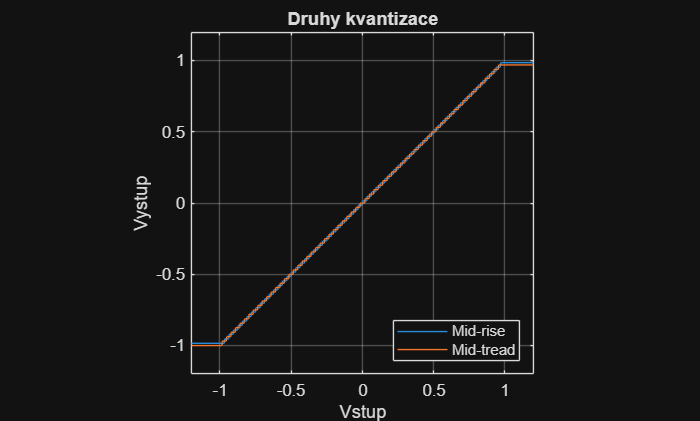

clear all;
close all;
clc;

% Vstupní signál, který nabývá hodnot od -1,2 do 1,2 o délce 1000 vzorků
x_quant = linspace(-1.2, 1.2, 1000);

% Bitová hloubka
bits = 2;

[y_midrise, ~] = quantize_signal(x_quant, bits, "mid_rise");
[y_midtread, ~] = quantize_signal(x_quant, bits, "mid_tread");

figure(1);
plot(x_quant, y_midrise);
hold on;
plot(x_quant, y_midtread);
hold off;
title("Druhy kvantizace");
legend(["Mid-rise", "Mid-tread"], Location="southeast");
xlim([-1.2, 1.2]);
ylim([-1.2, 1.2]);
xlabel("Vstup");
ylabel("Vystup");
pbaspect([1 1 1]);
grid on;

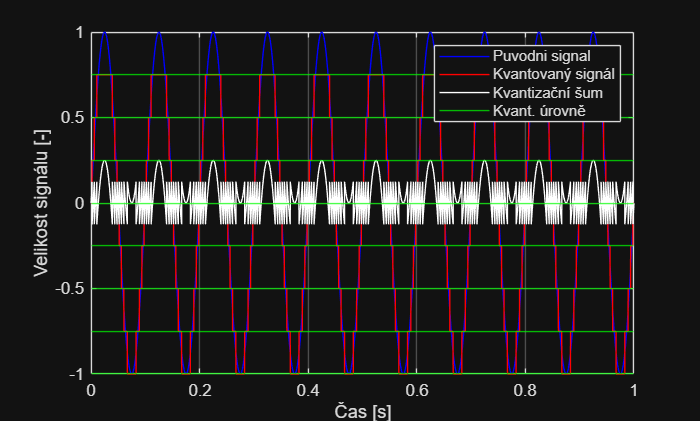

% Zobrazení kvantizace v časové oblasti

clear all;
close all;
clc;

[t, y_sine] = generate_sine(1, 1, 0, 48000, 10);

% Bitová hloubka
bits = 3;

[y_quantized, quant_levels] = quantize_signal(y_sine, bits, "mid_tread");

% Výpočet rozdílového signálu (kvantizačního šumu)
noise = y_sine - y_quantized;

figure (2);
plot(t, y_sine, "b");
hold on;
plot(t, y_quantized, "r"); 
hold on;
plot(t, noise, "w");
hold on;
yline(quant_levels, "g");
hold off;
legend(["Puvodni signal", "Kvantovaný signál", "Kvantizační šum", "Kvant. úrovně"]);
xlabel("Čas [s]");
ylabel("Velikost signálu [-]");
xlim([0, 1]);
ylim([-1, 1]);
grid on;


sqnr = calculate_sqnr(y_sine, noise)

sqnr = 16.4715